clc;
clear;
close all;

%% PARAMETERS
N = 1e5;                % Number of bits
Rb = 1e9;               % Bit rate (1 Gbps)
Tb = 1/Rb;              % Bit duration
Fs = 10*Rb;             % Sampling frequency
dt = 1/Fs;

t = 0:dt:N*Tb-dt;       % Time vector

%% TRANSMITTER

% Generate random binary data
data = randi([0 1], 1, N);

% OOK modulation (NRZ)
tx_signal = repelem(data, Fs/Rb);

% Optical power scaling
P_tx = 1;               % Transmit optical power
opt_signal = P_tx * tx_signal;

%% OPTICAL CHANNEL

% Fiber attenuation (dB/km)
L = 10;                 % Fiber length (km)
alpha = 0.2;            % dB/km

attenuation = 10^(-alpha*L/10);

% Apply attenuation
rx_opt_signal = opt_signal * attenuation;

% Add noise (AWGN)
SNR_dB = 20;
rx_opt_signal_noisy = awgn(rx_opt_signal, SNR_dB, 'measured');

%% RECEIVER (PHOTODETECTION)

R = 1;  % Responsivity (A/W)

% Convert optical to electrical signal
rx_elec_signal = R * rx_opt_signal_noisy;

%% SAMPLING & DECISION

samples = rx_elec_signal(Fs/Rb:Fs/Rb:end);

% Threshold detection
threshold = max(samples)/2;
rx_bits = samples > threshold;

%% BER CALCULATION

[num_errors, BER] = biterr(data, rx_bits);

fprintf('Bit Error Rate (BER) = %e\n', BER);

Bit Error Rate (BER) = 0.000000e+00


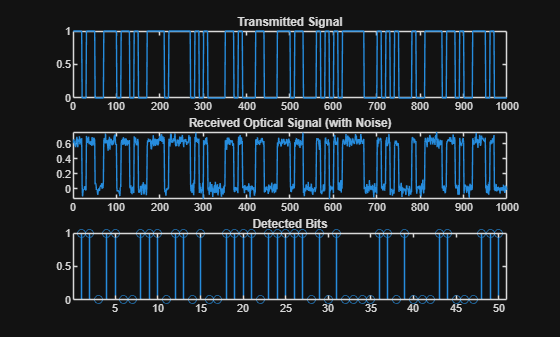


%% PLOTTING

figure;

subplot(3,1,1);
plot(tx_signal(1:1000));
title('Transmitted Signal');

subplot(3,1,2);
plot(rx_opt_signal_noisy(1:1000));
title('Received Optical Signal (with Noise)');

subplot(3,1,3);
stem(rx_bits(1:50));
title('Detected Bits');